# Examen Calcul Numeric $-$ Set 2 $-$ 14 iunie (restanță)

## Student: *Petec Răzvan-Gabriel*

## Grupa: *235*

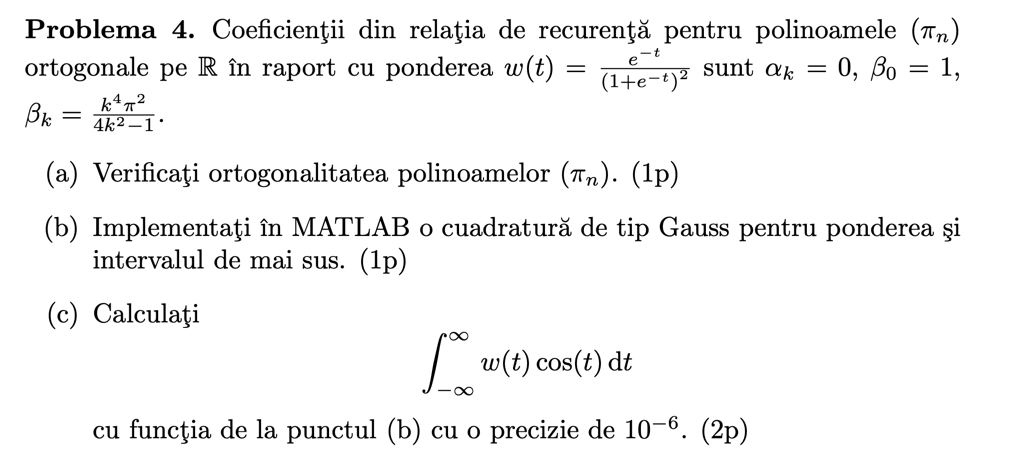

## Solutie

syms t;
w=exp(-t)/(1+exp(-t))^2

$$w = \frac{{\mathrm{e}}^{-t}}{{\left({\mathrm{e}}^{-t}+1\right)}^{2}}$$

### Subpunctul (a)

Polinoamele $\pi_k$ sunt date de relatia de recurenta: $\pi_{k+1} \left(x\right)=\left(x-\alpha_k \right)\pi_k \left(x\right)-\beta_k \pi_k \left(x\right),\pi_{-1} \left(x\right)=0,\pi_0 \left(x\right)=1\ldotp$ Din enunt, rezulta ca: $\begin{array}{l}
\pi_{k+1} \left(x\right)=x\pi_k \left(x\right)+\frac{k^4 \pi^2 }{4k^2 -1}\pi_{k-1} \left(x\right),\mathrm{pentru}\;k\ge 1,\;\pi_1 \left(x\right)=x\pi_0 \left(x\right)-\pi_{-1} \left(x\right)=x\\
\pi_2 \left(x\right)=x\pi_1 \left(x\right)-\pi_0 \left(x\right)\frac{\pi^2 }{3}=x^2 -\frac{\pi^2 }{3}
\end{array}$

function pi_1=nth_poly_sym(n, x)
    if n==-1, pi_1=0; return; end
    if n==0, pi_1=1; return; end
    
    pi_0=1; pi_1=x;
    for k=1:n-1
        pi_kn=x*pi_1 - (k^4*sym(pi)^2)/(4*k^2-1)*pi_0;
        pi_0=pi_1;
        pi_1=pi_kn;
    end

mat_orto =            1.0000000000001     -5.15651487170367e-19     -9.71445146547012e-17     -7.79961085071805e-18      1.16573417585641e-15      5.83468808967341e-17
     -5.15651487170367e-19          3.28986813369645     -1.21929822370514e-17      2.51534904016637e-15      1.59821407779653e-16     -3.01980662698043e-14
     -9.71445146547012e-17     -1.21929822370514e-17          34.6343434787564     -2.72234124098645e-16       6.3948846218409e-14      1.40000135278961e-14
     -7.79961085071805e-18      2.51534904016637e-15     -2.72234124098645e-16          791.085964999196      3.09168636797197e-15      4.71089833808946e-12
      1.16573417585641e-15      1.59821407779653e-16       6.3948846218409e-14      3.09168636797197e-15           31726.549421898      4.75553361790963e-13
      5.83468808967341e-17     -3.01980662698043e-14      1.40000135278961e-14      4.71089833808946e-12      4.75553361790963e-13          1976821.28665242


end

Ponderea $w\left(t\right)$ este o functie para $\left(w\left(-t\right)=\frac{e^t }{{\left(1+e^t \right)}^2 }=\frac{e^t }{e^{2t} {\left(1+e^{-t} \right)}^2 }=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }=w\left(t\right)\right)$

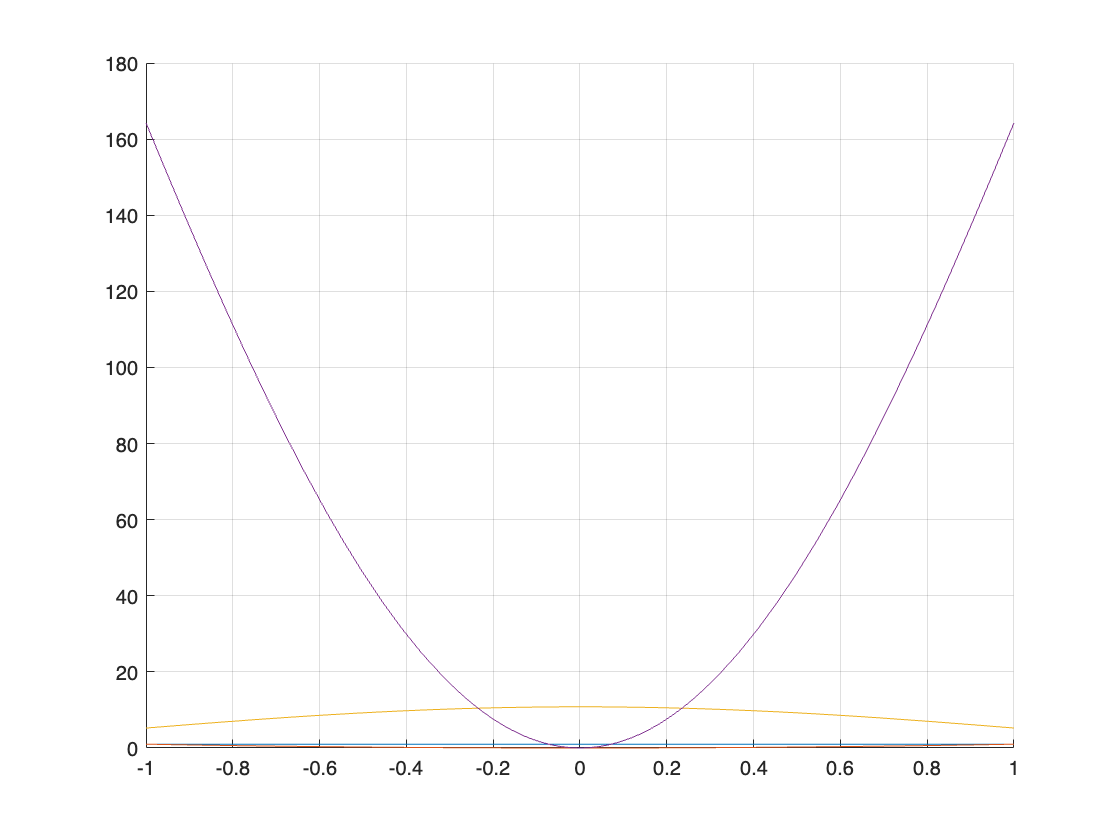

n=5;
mat_orto=zeros(n, n);
for i=0:n
    pi_i=nth_poly_sym(i,t);
    for j=0:n

        pi_j=nth_poly_sym(j,t);
        mat_orto(i+1,j+1)=vpaintegral(matlabFunction(w*pi_i*pi_j), -inf, inf);
    end
end
mat_orto

Se observa ca poligoanele sunt ortogonale 2 cate 2.

#### Demonstratie

Fie $i\not= j$. Atunci:


$$\begin{array}{l}
\left(\pi_i ,\pi_j \right)=\int_{-\infty }^{\infty } w\left(t\right)\pi_i \left(t\right)\pi_j \left(t\right)\;\mathrm{dt}=\int_{-\infty }^{\infty } w\left(t\right)\left({t\;\pi }_{i-1} \left(t\right)+\frac{i^4 \pi^2 }{4i^2 -1}\pi_{i-2} \left(t\right)\right)\left({t\;\pi }_{j-1} \left(t\right)+\frac{j^4 \pi^2 }{4j^2 -1}\pi_{j-2} \left(t\right)\right)\mathrm{dt}=\\
\;\;\;\;\;\;\;\;\;\;\;\;\;=\int_{-\infty }^{\infty } w\left(t\right)t^2 \pi_{i-1} \left(t\right)\pi_{j-1} \left(t\right)+w\left(t\right)t\frac{i^4 \pi^2 }{4i^2 -1}\pi_{i-2} \left(t\right)\pi_{j-1} \left(t\right)+w\left(t\right)t\frac{j^4 \pi^2 }{4j^2 -1}\pi_{j-2} \left(t\right)\pi_{i-1} \left(t\right)+w\left(t\right)\frac{i^4 \pi^2 }{4i^2 -1}\pi_{i-2} \left(t\right)\frac{j^4 \pi^2 }{4j^2 -1}\pi_{j-2} \left(t\right)\;\;\mathrm{dt}
\end{array}$$


Observam ca, pentru ca $\left(\pi_i ,\pi_j \right)=0$ este necesar ca:

- $\int_{-\infty }^{\infty } w\left(t\right)t^2 \pi_{i-1} \left(t\right)\pi_{j-1} \left(t\right)\mathrm{dt}=0$, ceea ce se poate obtine din recursivitate.

- $\int_{-\infty }^{\infty } w\left(t\right)t^2 \pi_{i-2} \left(t\right)\pi_{j-2} \left(t\right)\mathrm{dt}=0$, ceea ce se poate obtine din recursivitate (inmultind cu o functie para, nu va afecta paritatea).

- $\int_{-\infty }^{\infty } w\left(t\right)t\frac{i^4 \pi^2 }{4i^2 -1}\pi_{i-2} \left(t\right)\pi_{j-1} \left(t\right)+w\left(t\right)t\frac{j^4 \pi^2 }{4j^2 -1}\pi_{j-2} \left(t\right)\pi_{i-1} \left(t\right)\;\mathrm{dt}=0$. Aici trebuie tratat cazul cand $i=j+1\;/\;j=i+1$, altfel se poate obtine din recursivitate.

Pentru cazurile cu recursivitate, problema se reduce la a arata ca $\left(\pi_0 ,\pi_1 \right)=\left(\pi_1 ,\pi_0 \right)=\left(\pi_0 ,\pi_2 \right)=\left(\pi_2 ,\pi_0 \right)=0$, ceea ce se poate observa direct in tabelul aratat anterior.

Pentru cazul $i=j+1$ (echivalent cu $j=i+1$), unul dintre membrii se poate reduce, si va ramane integrala:

$\int_{-\infty }^{\infty } w\left(t\right)t\frac{i^4 \pi^2 }{4i^2 -1}\pi_{j-1} \left(t\right)\pi_{j-1} \left(t\right)\mathrm{dt}$. 

clf; hold on; grid on;

$$exp\_quad = 0.272029054982$$

for j=0:3
    pi_j=nth_poly_sym(j,t);
    fplot(pi_j^2, [-1 1])
end

Se observa grafic ca $\pi_k^2$ este o functie para (trebuie demonstrat, dar nu e timp), deci integrala mentionata anterior va fi egala cu 0 (deoarece avem par * impar * par = impar).

Deci, in concluzie, polinoamele $\pi_i$ sunt ortogonale.

### Subpunctul (b)

#### Implementare simbolica:

Avem functia care ne da al $k$-lea polinom, deci putem sa gasim cuadratura de tip Gauss astfel:

function [nodes,coefs]=gauss_poly_quad_sym(n)
    syms x;
    w=exp(-x)/(1+exp(-x))^2;
    a=-sym(inf); b=sym(inf);
    pin=nth_poly_sym(n, x);
    nodes=simplify(solve(pin==0))';
    coefs=gauss_coefs_sym(w,a,b,nodes);
end

#### Implementare numerica:

function [I,nodes,coefs]=gauss_poly_quad_num(n, f)

aproximare gasita


n =     20


$$err = 0.0000005088095067120782907250480371587$$

I_crt =          0.272028546172626


I_prev =          0.272030206151788


    alpha=zeros(1,n);
    beta=[1 ((1:n-1).^4 * pi^2) ./ (4*(1:n-1).^2 -1)];

    J=diag(alpha)+diag(sqrt(beta(2:end)),-1)+diag(sqrt(beta(2:end)),1);
    [V,nodes]=eig(J,'vector');
    coefs=beta(1)*V(1,:).^2;
    I=coefs*f(nodes);
    nodes=nodes';
end

### Subpunctul (c)

#### Valoare asteptata

exp_quad=vpaintegral(@(x) exp(-x)/(1+exp(-x)).^2 .* cos(x), -inf, inf,'RelTol', 1e-12, 'AbsTol', 0)

#### Valoare reala

f=@(x) cos(x);
I_prev=0; I_crt=0;
for n=1:100
    I_crt=gauss_poly_quad_num(n,f);
    err=abs(I_crt - exp_quad);
    if err<1e-6
        disp("aproximare gasita")
        n, err, I_crt, I_prev
        break
    end
    I_prev=I_crt;
end

Observam ca de la 20 de noduri, diferenta absoluta intre valoarea asteptata si cea obtinuta este mai mica decat ${10}^{-6}$, deci pentru minim 20 de noduri vom avea o aproximatie de minim 6 zecimale.